EP14 - Projeto do controlador PI e PD via lugar das raízes

Data: 14 de maio

ARTHUR LORENCINI BERGAMASCHI

PEDRO GABRIEL GAMBERT DA SILVA

Usar rlocus ou rltool para os projetos.

1) Verifique o efeito do zero de um controlador PD sobre as respostas deste sistema, **escolhendo Kp e Kd de forma a obter a resposta mais rápida possível com UP<10%**. Não há especificação de erro em regime.

s = tf('s');
g = 10/(s+1)^4;

Vemos que o tempo para chegar na amplitude 10 é de uns 10 segundos.

Passo 1) Fazer o LR do kp

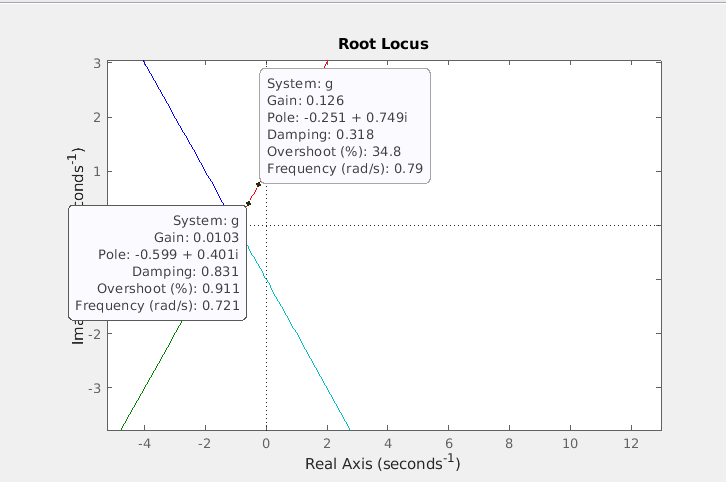

Encontramos uma faixa de Kp entre** [0.06 e 0.10]**. Aumentamos de 0.01 para 0.06 pois 0.01 dá um UP muito baixo.

kp_min = 0.06;
kp_max = 0.1;

id = 456

c =
 
  0.09102 s + 0.06
 
Continuous-time transfer function.
Model Properties

m =
 
            0.9102 s + 0.6
  ----------------------------------
  s^4 + 4 s^3 + 6 s^2 + 4.91 s + 1.6
 
Continuous-time transfer function.


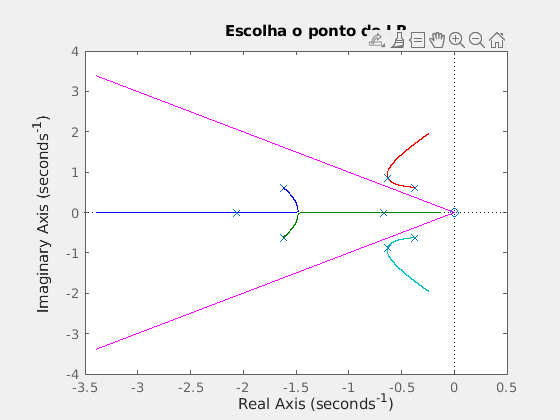

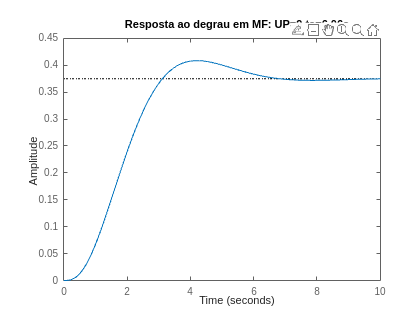

ans =
 
  0.09102 s + 0.06
 
Continuous-time transfer function.
Model Properties


projpd_lr(g,kp_min,1)

c_final = 0.09102*s + 0.06;
m_final = (0.09102*s + 0.6)/(s^4 + 4*s^3 + 6*s^2 + 4.846*s + 1.6);

id = 588

c =
 
  0.1174 s + 0.1
 
Continuous-time transfer function.
Model Properties

m =
 
             1.174 s + 1
  ---------------------------------
  s^4 + 4 s^3 + 6 s^2 + 5.174 s + 2
 
Continuous-time transfer function.


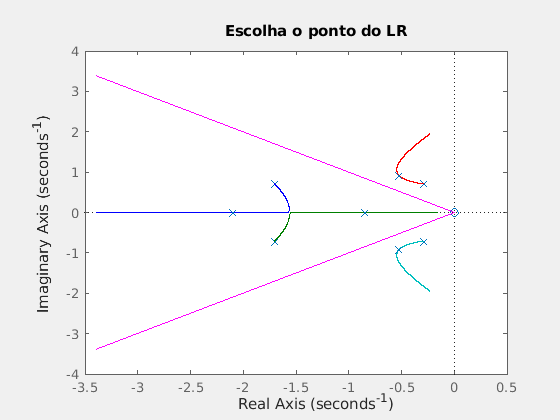

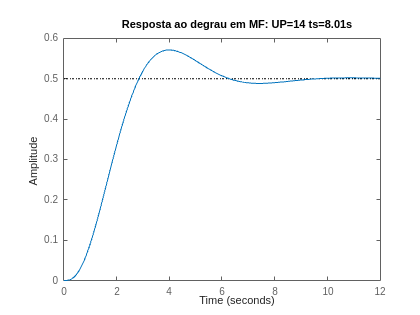

ans =
 
  0.1174 s + 0.1
 
Continuous-time transfer function.
Model Properties


projpd_lr(g,kp_max,1)

Como podemos ver, para Kp = 0.1 não conseguimos achar Kd que satisfaça a condição de UP<10%.

2) Plote a saída e o sinal de controle para uma entrada degrau no mesmo gráfico, analisando.

t = 0:0.1:15; 
u = (1 - m_final)*c_final % U = E*C; E = R - Y; M = R/Y

É notório obervar que U(s) é não causal. Logo, precisamos adicionar um filtro

para deixar o sinal de controle causal. 

O pólo tem que ficar mais a esquerda do eixo real para que seu efeito seja mínimo sobre o LR.

f = 1/(s+5); % LPF
figure;
hold on;
step(m,u*f,t)
legend('saída','controle')
grid on
hold off;

3) Verifique o efeito do zero de um controlador PI sobre as respostas deste sistema, escolhendo Kp e Ki de forma a obter a resposta mais rápida possível com UP<10%.

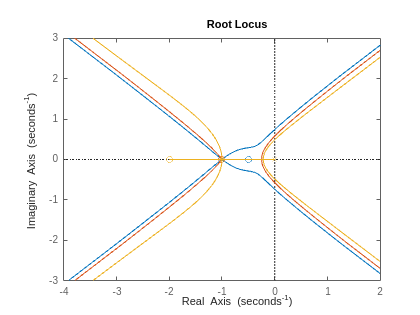

c_1 = kp_1*(s+ 0.5)/s; % zero em -0.5
c_2 = kp_2*(s+ 1)/s; % zero em -1
c_3 = kp_3*(s + 2)/s; % zero em -2
rlocus(g*c_1,g*c_2,g*c_3)

Se o nosso objetivo é buscar uma resposta rápida e sem sobreelevação, 

então o zero em -0.5 faz com que os pólos dominantes fiquem mais perto da origem.

c =
 
  0.03841 s + 0.0192
  ------------------
          s
 
Continuous-time transfer function.
Model Properties

m =
 
                0.3841 s + 0.192
  ---------------------------------------------
  s^5 + 4 s^4 + 6 s^3 + 4 s^2 + 1.384 s + 0.192
 
Continuous-time transfer function.


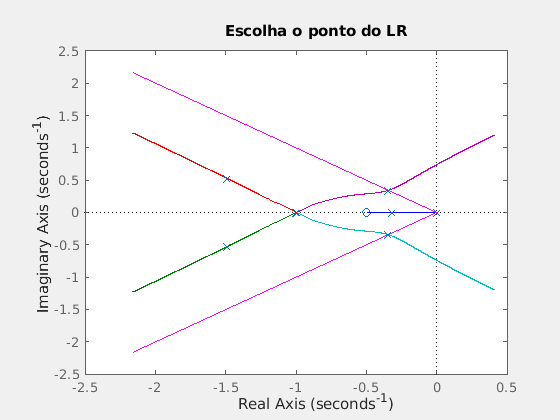

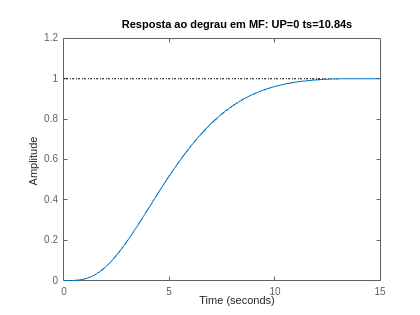

ans =
 
  0.03841 s + 0.0192
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


projpi_lr(g,0.5,1)

c_pi_final = (0.03841*s + 0.0192)/s;
m_pi_final = feedback(c_pi_final*g,1)

m_pi_final =
 
                0.3841 s + 0.192
  ---------------------------------------------
  s^5 + 4 s^4 + 6 s^3 + 4 s^2 + 1.384 s + 0.192
 
Continuous-time transfer function.
Model Properties


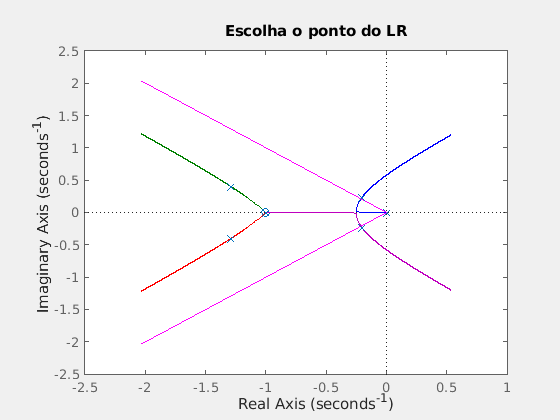

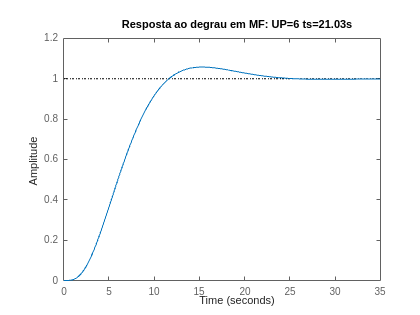

ans =
 
  0.0174 s + 0.0174
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


projpi_lr(g,1,1)

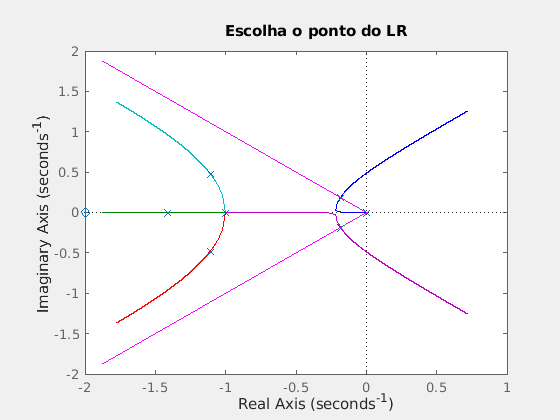

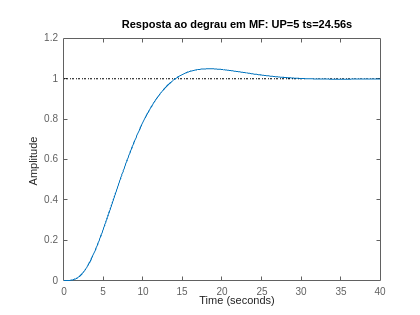

ans =
 
  0.007201 s + 0.0144
  -------------------
           s
 
Continuous-time transfer function.
Model Properties


projpi_lr(g,2,1)

4) Plote no mesmo gráfico a saída e o sinal de controle para uma entrada degrau, analisando.

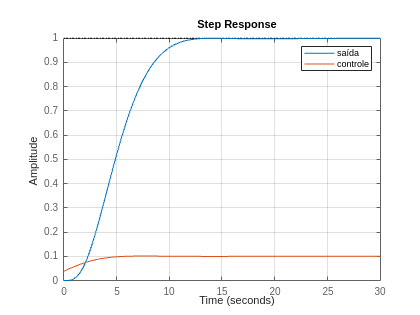

t = 0:0.1:30; 
% Sinal de Controle para R(s) = 1/s;
u = (1 - m_pi_final)*c_pi_final; % U = E*C; E = R - Y; M = R/Y
figure;
hold on;
step(m_pi_final,u,t)
legend('saída','controle')
grid on
hold off;

5) Plote no mesmo gráfico a saída e o sinal de controle para uma entrada de distúrbio somada ao sinal de controle, analisando.

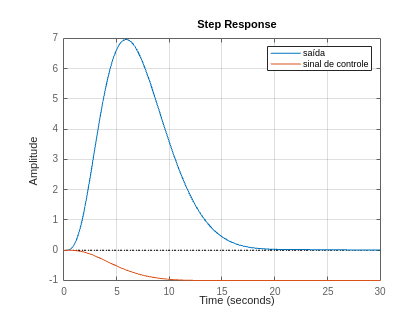

t = 0:0.1:30; 
y = g/(1+ c_pi_final*g); % resposta da saída ao distúrbio;
u = -y*c_pi_final; % sinal de controle para R(s) = 0;
step(y,u,t)
legend('saída','sinal de controle')
grid on

O sistema não consegue sumir com o distúrbio durante o período transitório. O controlador é capaz apenas de zerar o efeito do distúrbio para o regime permanente.